# Controllo della temperatura di una casa

## Descrizione del problema

L'obiettivo del progetto è regolare la temperatura di una casa utilizzando un controllore MPC. Si ipotizza che la casa non condivida alcun muro esterno con altre abitazioni, che i ﬂussi d'aria tra le stanze della casa siano trascurabili e che il riscaldamento della casa sia affidato a tre termosifoni, uno per ogni stanza. La pianta della casa in oggetto è mostrata nella figura seguente:

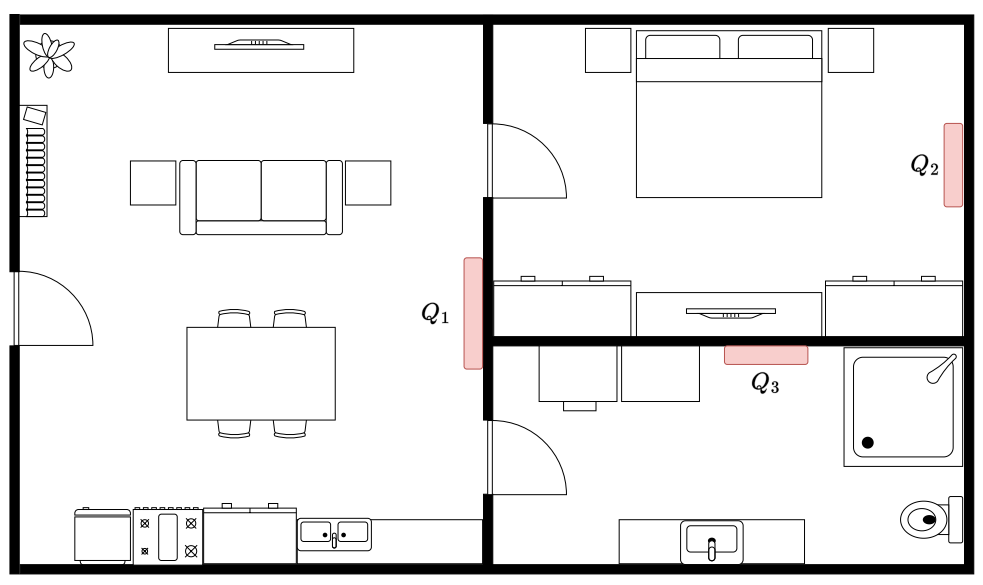

Figura 1: Planimetria della casa.

La dinamica della temperatura all’interno della casa è deﬁnita dalle equazioni seguenti:

$\begin{cases}
C_1\dot{T}_1(t) = Q_1(t) - k_{1,2}(t)(T_1(t)-T_2(t)) - k_{1,3}(t)(T_1(t)-T_3(t)) - k_{ext}(T_1(t)-T_{ext})\\
C_2\dot{T}_2(t) = Q_2(t) + k_{1,2}(t)(T_1(t)-T_2(t)) - k_{2,3}(t)(T_2(t)-T_3(t)) - k_{ext}(T_2(t)-T_{ext})\\
C_3\dot{T}_3(t) = Q_3(t) + k_{1,3}(t)(T_1(t)-T_3(t)) + k_{2,3}(t)(T_2(t)-T_3(t)) - k_{ext}(T_3(t)-T_{ext})\\
\dot{Q}_1 = (Q_{1,r}(t)-Q_1(t))/\tau_1 \\
\dot{Q}_2 = (Q_{2,r}(t)-Q_2(t))/\tau_2\\
\dot{Q}_3 = (Q_{3,r}(t)-Q_3(t))/\tau_3
\end{cases}$  con $k_{i,j} ={\bar{k} }_{i,j} +\frac{4}{1+e^{-0\ldotp 5{\left\|T_i \left(t\right)-T_j \left(t\right)\right\|}_2 } }$

Il significato delle grandezze presenti nelle precedenti equazioni è il seguente:

- $T_i\;[K]$ è la temperatura della i-esima stanza;

- $T_{ext}\;[K]$ è la temperatura esterna, ipotizzata costante.

- $C_i\;[J/s]$ è la capacità termica della i-esima stanza;

- $k_{i,j}\;[W/K]$ è un parametro che regola lo scambio di calore tra l’i-esima e la j-esima stanza;

- $k_{ext}\;[W/K]$ è un parametro che regola lo scambio di calore tra le stanze della casa e l’esterno;

- $Q_i\;[W]$ è la potenza termica dell’i-esimo termosifone;

- $Q_{i,r}\;[W]$ è la potenza termica di riferimento dell’i-esimo termosifone;

- $\tau_i\;[s]$ è la costante di tempo dell’i-esimo termosifone. 

I parametri noti sono riportati nella tabella seguente:


$$\matrix{
\textbf{Parametro} & \textbf{Valore} & \textbf{Unità}    \cr
C_1 		& 6800 		& J/s	        \cr
C_2			& 5600		& J/s		\cr
C_3	        	& 5100 		& J/s		\cr
\bar{k}_1 		& 15 		& W/K	        \cr
\bar{k}_2		& 20	         	& W/K		\cr
\bar{k}_3	       	& 15 		& W/K		\cr
k_{ext}	       	& 8 	        	& W/K		\cr
T_{ext}	       	& 278        	& K    		\cr
\tau_1 		& 400 		& s	                \cr
\tau_2		& 450		& s		        \cr
\tau_3        	& 450 		& s	        	\cr
}$$


Tabella 1: Parametri noti del sistema in esame.

La potenza erogata dai tre termosifoni è non-negativa e mai superiore ai 150W, mentre la temperatura all’interno delle tre stanze non deve mai scendere al di sotto dei 286K.

Gli ingressi controllati del sistema sono le potenze di riferimento dei tre termosifoni, $Q_{i,r}$, $i \in \{1,2,3\}$.

L’obiettivo del lavoro è progettare un controllore MPC in grado di portare il sistema dalla condizione iniziale $(T_1, T_2 , T_3 , Q_1 , Q_2 , Q_3 ) = (288, 288, 288, 0, 0, 0)$ all’equilibrio $(293, 293, 293, 120, 120, 120)$, rispettando sempre i vincoli, e simulare il funzionamento del sistema in anello chiuso.

## Parametri costanti del modello della casa

Inizialmente, si creano delle varibili per salvare tutti i parametri noti del modello.

T_ext = 278; % [K], temperatura esterna ipotizzata costante
C = [6800 5600 5100]; % [J/s], capacità termica della i-esima stanza
k_bar = [15 20 15]; % [W/K], scambio di calore fra l'i-esima e la j-esima stanza 
k_ext = 8; % [W/K], scambio di calore fra les stanze e l'esterno
Q_ref = [150 150 150]; % [W], potenza termica di riferimento dell'i-esimo termosifone
tau = [400 450 450]; % [s], costante di tempo dell'i-esimo termosifone

## Equazioni del sistema in forma di stato

Prima di procedere ad analizzare il sistema, è necessario riscrivere le equazioni della sua dinamica nello spazio degli stati. Si definiscono il vettore degli stati, $\mathbf{x}$, ed il vettore delle uscite, $\mathbf{u}$:

$\mathbf{x} = [x_1, x_2, x_3, x_4, x_5, x_6 ]'
:= [T_1, T_2, T_3, Q_1, Q_2, Q_3]'$, $\mathbf{x}\in \mathbb{R}^6$

$\mathbf{u} = [u_1, u_2, u_3]' := [Q_{1,r},\;Q_{2,r},\;Q_{3,r}]'$, $\mathbf{u}\in \mathbb{R}^3$

Il sistema diventa quindi:

$\begin{cases}
C_1\dot{x}_1(t) = x_4(t) - k_{1,2}(t)(x_1(t)-x_2(t)) - k_{1,3}(t)(x_1(t)-x_3(t)) - k_{ext}(x_1(t)-T_{ext})\\
C_2\dot{x}_2(t) = x_5(t) + k_{1,2}(t)(x_1(t)-x_2(t)) - k_{2,3}(t)(x_2(t)-x_3(t)) - k_{ext}(x_2(t)-T_{ext})\\
C_3\dot{x}_3(t) = x_6(t) + k_{1,3}(t)(x_1(t)-x_3(t)) + k_{2,3}(t)(x_2(t)-x_3(t)) - k_{ext}(x_3(t)-T_{ext})\\
\dot{x}_4 = (u_1(t)-x_4(t))/\tau_1 \\
\dot{x}_5 = (u_2(t)-x_5(t))/\tau_2\\
\dot{x}_6 = (u_3(t)-x_6(t))/\tau_3
\end{cases}$ con $k_{i,j} ={\bar{k} }_{i,j} +\frac{4}{1+e^{-0\ldotp 5{\left\|x_i \left(t\right)-x_j \left(t\right)\right\|}_2 } }$

Si isolano gli stati e le uscite, in modo da ricavare le matrici A e B. Il sistema diventa dunque:

TODO: continua da qui

% eq = [293 293 293 120 120 120];
syms T1 T2 T3 Q1 Q2 Q3;
% T1 = 293;
% T2 = 293;
% T3 = 293;
% Q1 = 120;
% Q2 = 120;
% Q3 = 120;
matrix_TvsT = [-((k_bar(2)+(1/(1+exp(-0.5*(norm((T1-T2),2))))))+((k_bar(3)+(1/(1+exp(-0.5*(norm((T1-T3),2))))))+k_ext))/C(1), (k_bar(2)+(1/(1+exp(-0.5*(norm((T1-T2),2)))))/C(1)), (k_bar(3)+(1/(1+exp(-0.5*(norm((T1-T3),2)))))/C(1));
                (k_bar(1)+(1/(1+exp(-0.5*(norm((T1-T2),2)))))/C(2)), -((k_bar(1)+(1/(1+exp(-0.5*(norm((T1-T3),2))))))+((k_bar(3)+(1/(1+exp(-0.5*(norm((T2-T3),2))))))+k_ext))/C(2), (k_bar(3)+(1/(1+exp(-0.5*(norm((T2-T3),2)))))/C(2));
                (k_bar(1)+(1/(1+exp(-0.5*(norm((T1-T3),2)))))/C(3)), (k_bar(2)+(1/(1+exp(-0.5*(norm((T2-T3),2)))))/C(2)), -((k_bar(1)+(1/(1+exp(-0.5*(norm((T1-T3),2))))))+((k_bar(2)+(1/(1+exp(-0.5*(norm((T2-T3),2))))))+k_ext))/C(3)];
matrix_TvsQ = eye(3).*(1./C);
matrix_QvsT = zeros(3,3);
matrix_QvsQ = -eye(3).*(1./tau);
A = [matrix_TvsT, matrix_TvsQ;
     matrix_QvsT, matrix_QvsQ];
jacobian(A(1,:));

## Vincoli su stato e ingresso

Successivamente, si definiscono i vincoli esistenti su stato e ingresso del sistema.

x_min_temp = 268.*ones(3,1); % Vincolo di minimo sulla temperatura dell'i-esima stanza
x_min_power = zeros(3,1); % Vincolo di minimo sulla potenza dell'i-esimo termosifone
x_max_power = 150.*ones(3,1); % Vincolo di minimo sulla potenza dell'i-esimo termosifone
u_min = zeros(3,1); % Vincolo di minimo sulla potenza dell'i-esimo termosifone
u_max = 150.*ones(3,1); % Vincolo di minimo sulla potenza dell'i-esimo termosifone

## Punti di equilibrio